# Clustering clients with k-means to estimate their preferred time horizon of investment

## Objective

In this file the main objective is to segment clients in order to determine clusters of clients with similar characteristics. This information will then be used to make a plausible estimate on the time horizon of investment preferred by each client. Thus the new dataset is divided into training and testing set and two classification models are built, specifically one for the accumulation products and the other for the income ones. Then precision, recall and F1 score will be computed, confusion matrix and ROC curve will be plotted and the results will be commented.

In this case, only numerical features are used: age, financial education, risk propensity, income and wealth. Therefore the clustering algorithm applied is k-means with euclidean distance.

#### *Load data *

close all
clc
load('Needs.mat') %original dataset

### Preparing data

We extract the numerical variables of interest and scale them.

We also make a Box Cox transformation on *Wealth *and *Income* and we choose to apply the logarithm for a clearer interpretation of results.

We have chosen to consider the whole dataset in order to have more precise results.

% Numerical
Data = Needs(:,2:8); % Exclude 1st col = ID and Income/accumulation labels
logWealth = log(Data.Wealth); %log trasformation of data
logIncome = log(Data.Income); %logtrasformation of data

XNum =[rescale(Data.Age) rescale(Data.FinancialEducation)...
    rescale(Data.RiskPropensity) rescale(logIncome) rescale(logWealth)];
X=XNum;

## Unsupervised clustering with mixed categorical and continuous data

### Clustering witk k-means

We decided to set a varying number of clusters, between 3 to 10, and then compare the results.

Since the `kmeans` function is not guaranteed to converge to a global minimum for the problem, we will set the hyperparameter `'replicates'` to 5, so that the algorithm is run 5 times and the best result is returned, and the maximum number of iterations to 200, instead of the default of 100.

#### **3 clusters**

[IDX3, C3, SUMD3, D3] = kmeans(X,3,'replicates',5,'MaxIter', 200);

#### **4 clusters**

[IDX4, C4, SUMD4, D4] = kmeans(X,4,'replicates',5,'MaxIter', 200);

#### **5 clusters**

[IDX5, C5, SUMD5, D5] = kmeans(X,5,'replicates',5,'MaxIter', 200);

#### 6 clusters

[IDX6, C6, SUMD6, D6] = kmeans(X,6,'replicates',5, 'MaxIter', 200);

#### **7 clusters**

[IDX7, C7, SUMD7, D7] = kmeans(X,7,'replicates',5,'MaxIter', 200);

#### 8 clusters

[IDX8, C8, SUMD8, D8] = kmeans(X,8,'replicates',5,'MaxIter', 200);

#### 9 clusters

[IDX9, C9, SUMD9, D9] = kmeans(X,9,'replicates',5,'MaxIter', 200);

#### 10 clusters

[IDX10, C10, SUMD10, D10] = kmeans(X,10,'replicates',5,'MaxIter', 200);

#### Clustering evaluation

We will use three criteria to evaluate the best number of clusters to consider for our problem.

**Calinski-Harabasz criterion** 

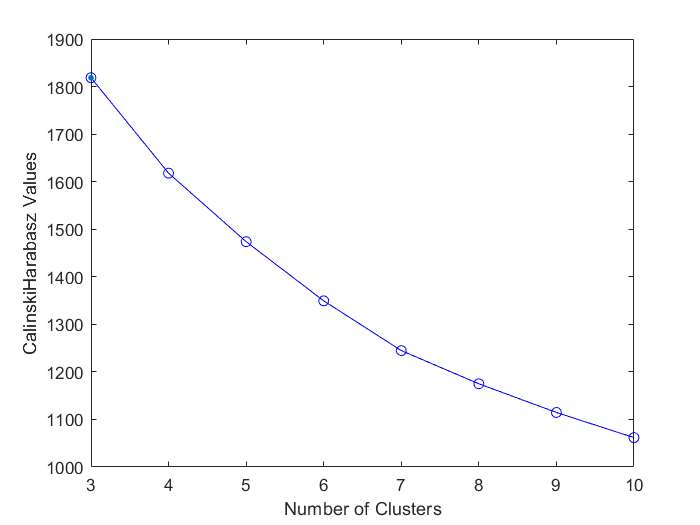

clust = [IDX3 IDX4 IDX5 IDX6 IDX7 IDX8 IDX9 IDX10];
eva1 = evalclusters(X,clust,'CalinskiHarabasz');
figure
plot(eva1)

eva1

eva1 =   CalinskiHarabaszEvaluation with properties:

    NumObservations: 5000
         InspectedK: [3 4 5 6 7 8 9 10]
    CriterionValues: [1.8186e+03 1.6179e+03 1.4738e+03 1.3494e+03 1.2448e+03 1.1750e+03 1.1147e+03 1.0618e+03]
           OptimalK: 3


The plot shows that the highest Calinski-Harabasz value occurs at 3 clusters, suggesting that the optimal number of clusters is 3.

**Davies-Bouldin criterion** 

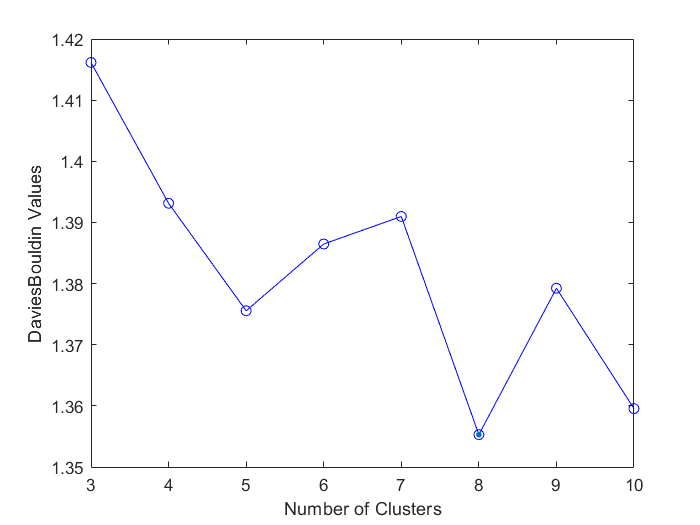

eva2 = evalclusters(X,clust,'DaviesBouldin');
figure
plot(eva2)

eva2

eva2 =   DaviesBouldinEvaluation with properties:

    NumObservations: 5000
         InspectedK: [3 4 5 6 7 8 9 10]
    CriterionValues: [1.4162 1.3931 1.3756 1.3865 1.3910 1.3553 1.3792 1.3595]
           OptimalK: 8


The plot shows that the lowest Davies-Bouldin value occurs at 8 clusters, suggesting that the optimal number of clusters is 8

**Silhouette criterion** 

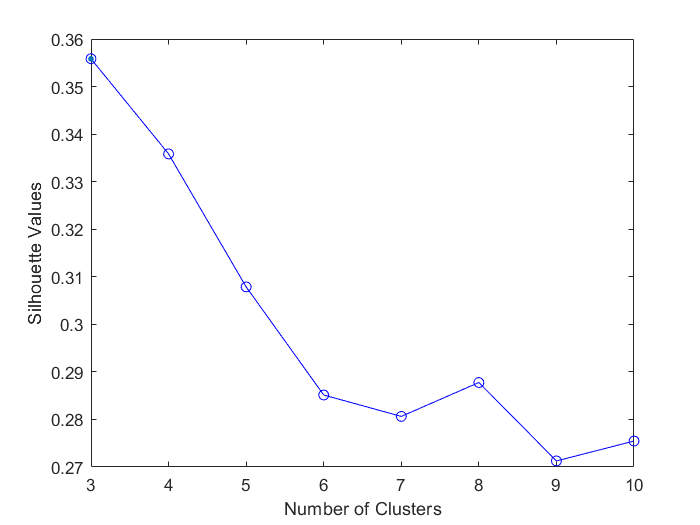

eva3 = evalclusters(X,clust,'Silhouette');
figure
plot(eva3)

eva3

eva3 =   SilhouetteEvaluation with properties:

    NumObservations: 5000
         InspectedK: [3 4 5 6 7 8 9 10]
    CriterionValues: [0.3558 0.3358 0.3079 0.2851 0.2806 0.2878 0.2713 0.2755]
           OptimalK: 3


The plot shows that the highest silhouette value occurs at 3 clusters, suggesting that the optimal number of clusters is 3.

Let's have a closer look at the silhouette of the most reasonable clusters hypothesis.

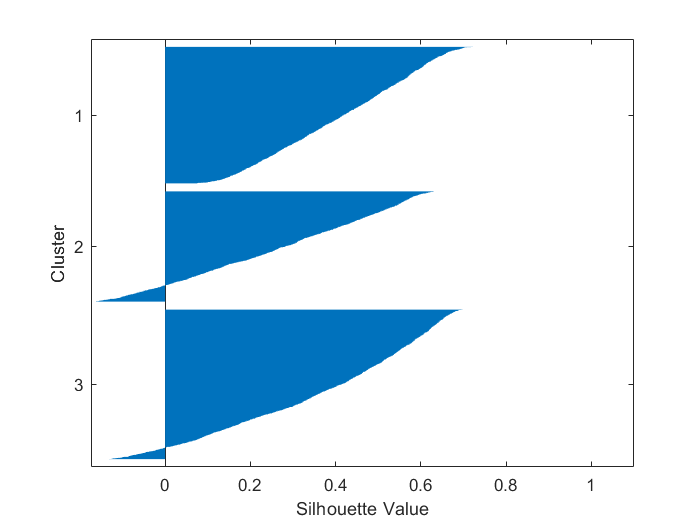

figure
silhouette(X,IDX3);

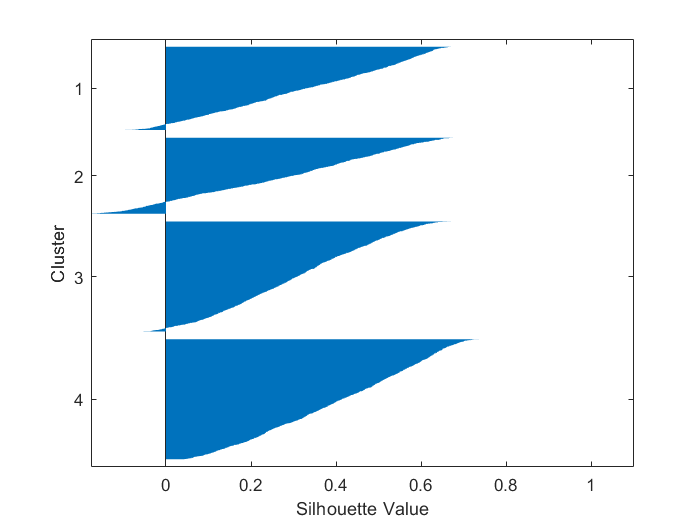

figure
silhouette(X,IDX4); 

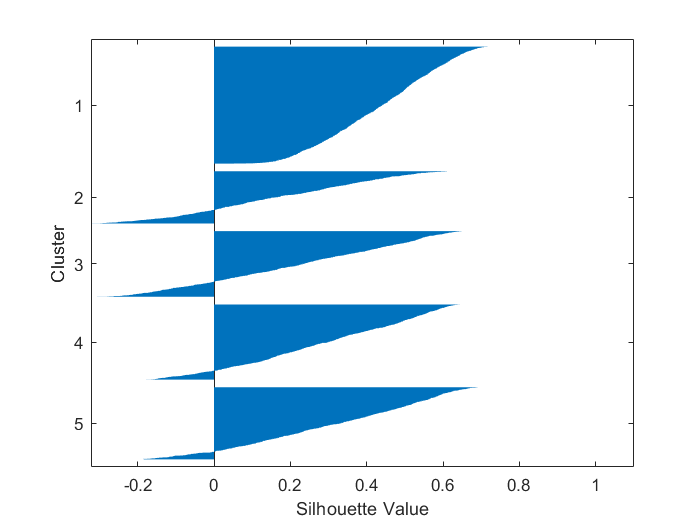

figure
silhouette(X,IDX5);

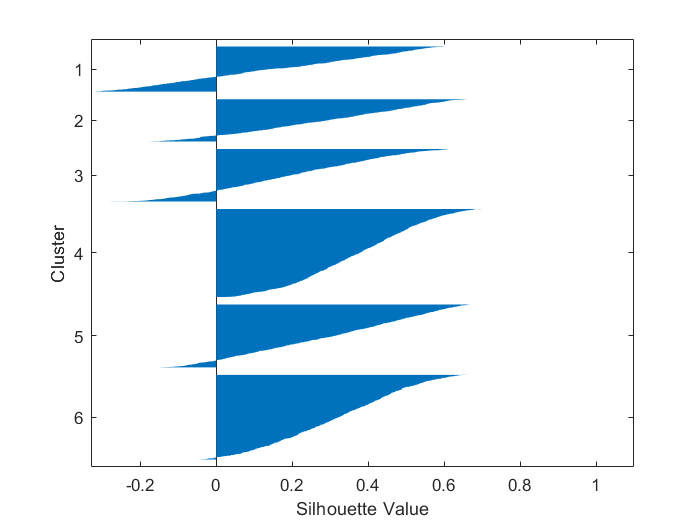

figure
silhouette(X,IDX6);

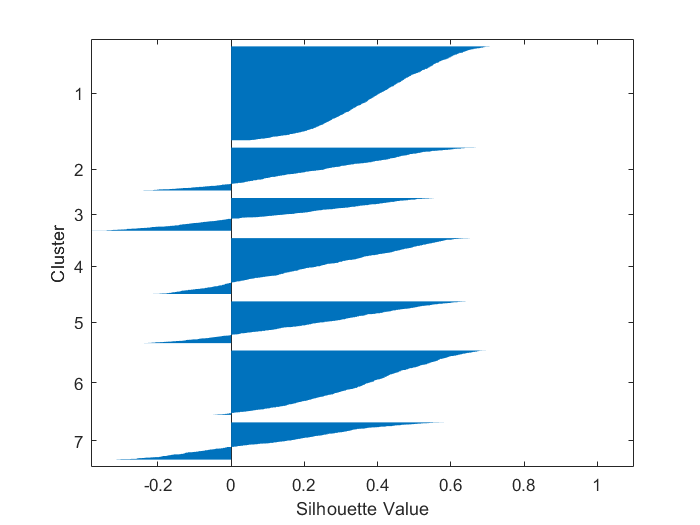

figure
silhouette(X,IDX7);

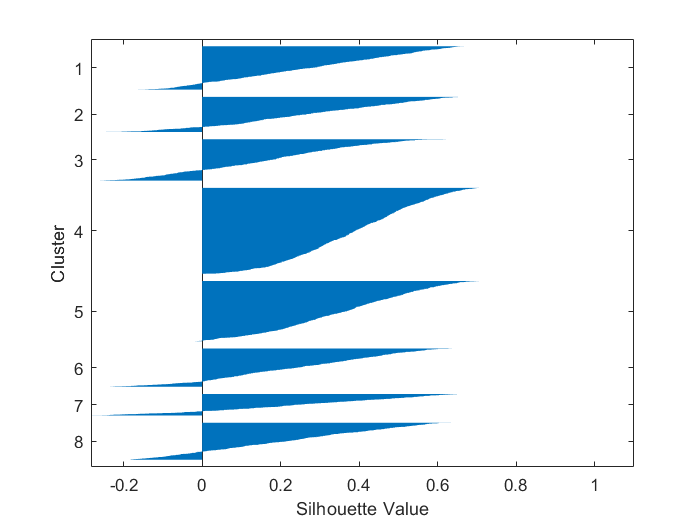

figure
silhouette(X,IDX8);

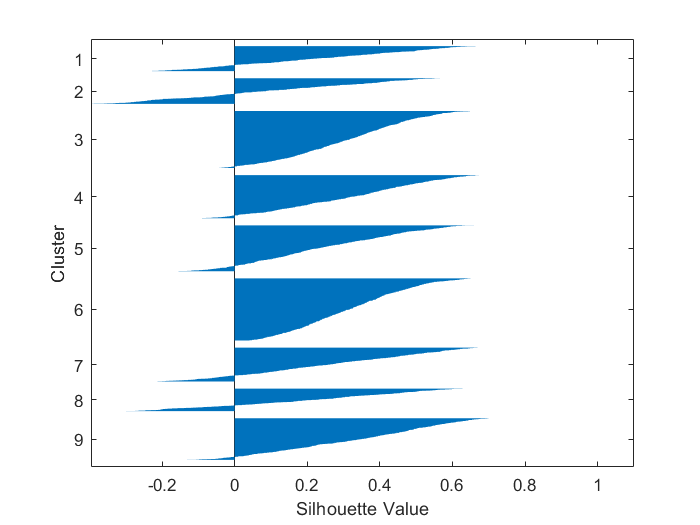

figure
silhouette(X,IDX9);

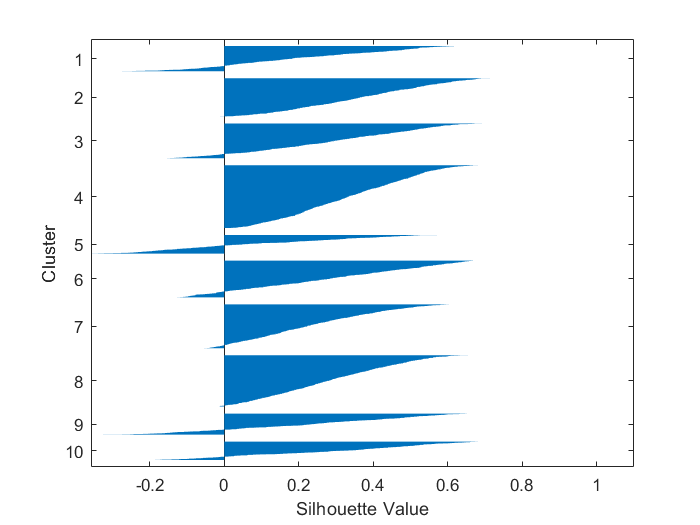

figure
silhouette(X,IDX10);

### **Conclusions**

The optimal number of clusters is 3, according to two out of the 3 criteria above. Despite this, we would like to have a wider range of years of time horizon and so a larger number of clusters. Therefore we choose to segment clients into 8 clusters and we believe it is a good compromise, especially observing the silhouette plot.

### Analyzing 3 clusters

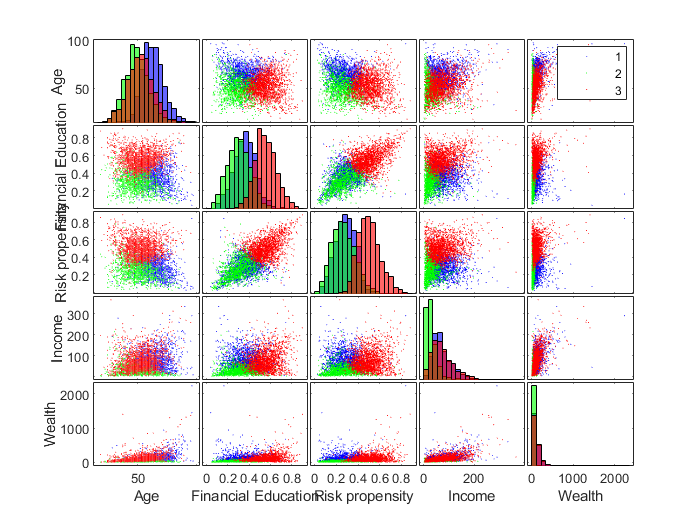

Data4Plot = [Data.Age  Data.FinancialEducation Data.RiskPropensity Data.Income Data.Wealth ];
xnames = {'Age', 'Financial Education', 'Risk propensity', 'Income', 'Wealth'};
gplotmatrix(Data4Plot(1:5000,:),[],IDX3, [],[],[],[],'grpbars', xnames)

We notice that there is a evident linear relationship between *Risk propensity* and *Financial education: *as clients are more acknowledged about financial markets, more they are prone to riskier investments.

ClusterCardinality = grpstats(X(:, 1),IDX3, 'numel');
ClusterCardinality = ClusterCardinality/sum(ClusterCardinality)

ClusterCardinality =     0.3444
    0.2784
    0.3772


All three clusters have similar size.

ClusterMedian = 100*grpstats(X(:,1:end),IDX3, @median)

ClusterMedian =    56.9620   37.6182   30.0717   68.3554   57.7484
   39.2405   30.8591   27.4632   50.6621   43.0386
   43.0380   59.1961   54.6106   69.0185   57.8068


We notice the first cluster is of the oldest people, the second of the youngest ones and the third of the relatively young people with higher risk propensity, income and wealth than the second group.

ClusterMeans= grpstats(X(:,1:end),IDX3, 'mean')

ClusterMeans =     0.5724    0.3742    0.3019    0.6848    0.5866
    0.3942    0.3118    0.2834    0.4949    0.4121
    0.4367    0.5997    0.5593    0.6776    0.5783


ClusterVariances= grpstats(X(:,1:end),IDX3, 'var')

ClusterVariances =     0.0142    0.0148    0.0123    0.0102    0.0065
    0.0176    0.0157    0.0162    0.0188    0.0095
    0.0200    0.0141    0.0149    0.0153    0.0100


Clustermins= grpstats(X(:,1:end),IDX3, 'min')

Clustermins =     0.1266         0    0.0004    0.1783    0.2346
         0    0.0126         0         0    0.0113
         0    0.1599    0.0965    0.1445         0


Clustermaxs= grpstats(X(:,1:end),IDX3, 'max')

Clustermaxs =     1.0000    0.8176    0.9514    0.9833    1.0000
    0.8608    0.8269    0.8762    0.9020    0.6354
    0.9747    1.0000    1.0000    1.0000    0.9392


### Analyzing 8 clusters

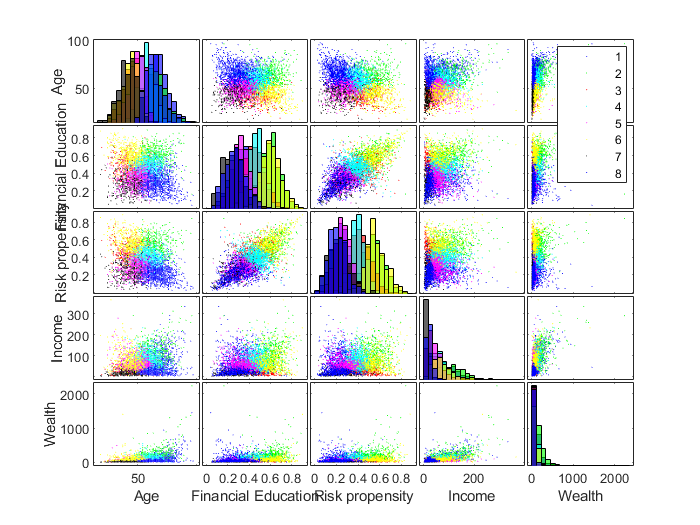

Data4Plot = [Data.Age  Data.FinancialEducation Data.RiskPropensity Data.Income Data.Wealth ];
xnames = {'Age', 'Financial Education', 'Risk propensity', 'Income', 'Wealth'};
gplotmatrix(Data4Plot(1:5000,:),[],IDX8, [],[],[],[],'grpbars', xnames)

ClusterCardinality = grpstats(X(:, 1),IDX8, 'numel');
ClusterCardinality = ClusterCardinality/sum(ClusterCardinality)

ClusterCardinality =     0.1198
    0.0966
    0.1140
    0.2368
    0.1662
    0.1052
    0.0594
    0.1020


The first cluster is slightly larger than the others.

ClusterMedian = 100*grpstats(X(:,1:end),IDX8, @median)

ClusterMedian =    64.5570   32.6612   25.2831   73.0682   61.9641
   58.2278   66.1341   60.5549   76.9705   67.3183
   35.4430   47.9929   47.4617   51.8954   45.9564
   50.6329   49.7477   42.9719   68.6685   58.1044
   40.5063   32.4649   27.2714   64.3765   48.7626
   32.9114   65.6637   61.7363   68.9809   55.3380
   30.3797   24.7782   22.6934   39.7281   33.0262
   58.2278   26.5372   21.1390   47.7417   47.4095


Median values are discussed in the next section to assign the Time Horizon.

ClusterMeans= grpstats(X(:,1:end),IDX8, 'mean')

ClusterMeans =     0.6536    0.3298    0.2509    0.7294    0.6274
    0.5954    0.6613    0.6066    0.7583    0.6804
    0.3463    0.4845    0.4838    0.5052    0.4512
    0.5019    0.4930    0.4300    0.6851    0.5811
    0.3955    0.3235    0.2763    0.6464    0.4849
    0.3208    0.6639    0.6309    0.6788    0.5535
    0.3002    0.2526    0.2346    0.3782    0.3055
    0.5893    0.2734    0.2157    0.4654    0.4704


ClusterVariances= grpstats(X(:,1:end),IDX8, 'var')

ClusterVariances =     0.0090    0.0138    0.0098    0.0072    0.0062
    0.0117    0.0117    0.0134    0.0098    0.0060
    0.0108    0.0117    0.0112    0.0125    0.0072
    0.0069    0.0081    0.0078    0.0069    0.0037
    0.0079    0.0089    0.0074    0.0067    0.0044
    0.0093    0.0112    0.0138    0.0135    0.0084
    0.0104    0.0142    0.0129    0.0153    0.0118
    0.0099    0.0141    0.0097    0.0110    0.0078


Clustermins= grpstats(X(:,1:end),IDX8, 'min')

Clustermins =     0.4304         0    0.0160    0.4723    0.4129
    0.3544    0.1446    0.2442    0.3531    0.3256
    0.0127    0.1511    0.1764    0.0681         0
    0.2658    0.1094    0.0965    0.3646    0.2346
    0.0759    0.0291    0.0124    0.4500    0.2505
         0    0.3686    0.2395    0.1947    0.0003
         0    0.0126    0.0105         0    0.0113
    0.3924    0.0179         0    0.0935    0.0485


Clustermaxs= grpstats(X(:,1:end),IDX8, 'max')

Clustermaxs =     0.9873    0.7670    0.7040    0.9833    0.9434
    0.9873    0.9844    0.9514    0.9835    1.0000
    0.6962    0.8821    0.8762    0.7853    0.6595
    0.7975    0.8577    0.7893    0.9169    0.8149
    0.5949    0.5890    0.5104    0.9502    0.8016
    0.5696    1.0000    1.0000    1.0000    0.9392
    0.6076    0.7741    0.6037    0.7167    0.6084
    1.0000    0.8269    0.6228    0.6813    0.7765


### Dividing data into 8 clusters

Data.Clusters=IDX8(:,1);

Here we provide a short description of each cluster, by comparing their medians:

- Old people, low risk propensity;

- Middle aged people, very rich, high risk propensity;

- Youngsters quite rich, larger income than wealth, average risk propensity and average financial education score;

- Middle aged people, quite rich, average risk propensity and average financial education score;

- Youngsters quite rich, larger income than wealth, average risk propensity and average financial education score;

- Youngsters very rich, larger income than wealth, high risk propensity and high financial education score;

- Youngsters quite poor, larger income than wealth, low risk propensity and low financial education score;

- Middle aged, poor, low risk propensity and low financial education score.

### Assigning the estimated time horizon of investment to each client

We decided to assign to each cluster a time period in years, between 2 and 9 years. We decided this range for two reasons. 

First of all, the dataset *Products*, that is subsequently used for the association of clients' needs and products, actually contains categories of products. Therefore we define the time horizon of investment as the time period during which the client might invest on the same category of products. Thus we do not assume that the client sticks on the same product for as long as seven years, for example. We assume that he/she might disinvest on one product as long as he/she invests on other products of the same category. This, in our opinion, reflects better the business reality of the financial world.

Secondly, many categories of products such as *Life insurance,* that are present in the dataset* Products, *require a time horizon of investment that is quite long by definition. Therefore our choice seems appropriate for our case.

The assignment is the following one:

- 2 years;

- 5 years;

- 8 years;

- 4 years;

- 7 years;

- 9 years;

- 6 years;

- 3 years.

The criteria used are the following, in order of importance:

- The younger the person, the greater the time horizon of investment: this seems reasonable as they have a greater life expectancy than older people;

- The higher the risk propensity the greater the time horizon of investment: for long term investments clients can take on more risk, since the market has many years to recover in the event of a pullback.

for i = 1:5000
    if (Data.Clusters(i) == 1) 
        Data.TimeHorizon(i)=2; 
    elseif (Data.Clusters(i) == 2) 
        Data.TimeHorizon(i)=5; 
    elseif (Data.Clusters(i) == 3) 
        Data.TimeHorizon(i)=8; 
    elseif (Data.Clusters(i) == 4) 
        Data.TimeHorizon(i)=4; 
    elseif (Data.Clusters(i) == 5) 
        Data.TimeHorizon(i)=7; 
    elseif (Data.Clusters(i) == 6) 
        Data.TimeHorizon(i)=9; 
    elseif (Data.Clusters(i) == 7) 
        Data.TimeHorizon(i)=6;
    elseif (Data.Clusters(i) == 8) 
        Data.TimeHorizon(i)=3;
    end
end

NOTE: The order of the clusters changes each time, therefore the above description may not correspond to the dataset obtained.

### Visualizing Time Horizon

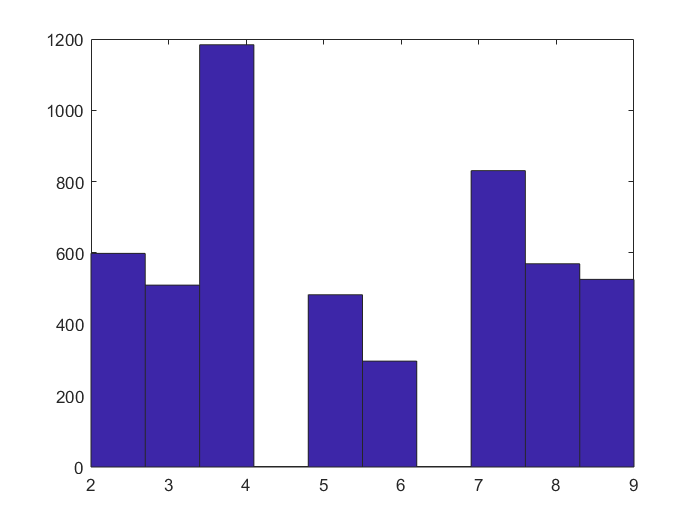

hist(Data.TimeHorizon)

### Saving this new dataset with the new variable Time Horizon

%NeedsclustNUM=Data;
%save("NeedsclustNUM.mat","NeedsclustNUM");
load("NeedsclustNUM.mat","NeedsclustNUM");
Data=NeedsclustNUM; % we load our dataset that we obtained in order to get the same results for the model

### Running the classification model with Time Horizon 

### **Preparing the data**

Data = [Data Needs(:,9:10)];

X =[rescale(Data.Age) Data.Gender rescale(Data.FamilyMembers) rescale(Data.FinancialEducation)...
    rescale(Data.RiskPropensity) rescale(logIncome) rescale(logWealth) rescale(Data.TimeHorizon)];

nObs = size(Data, 1);
idxPermutation = randperm(nObs);
X = X(idxPermutation,:); % random permutation
nObsTrain = round(0.75*nObs);

yInvIncTrain = Data.IncomeInvestment(1:nObsTrain);
yInvIncTest = Data.IncomeInvestment(nObsTrain+1:end);

yInvAccTrain = Data.AccumulationInvestment(1:nObsTrain);
yInvAccTest = Data.AccumulationInvestment(nObsTrain+1:end);

varNames = {'Age', 'Gender', 'Family', 'FinEdu', 'Risk', 'Income', 'Wealth', 'TimeHorizon'};

IncomeWealthRatio = zeros(nObs,1);
IncomeWealthRatio(Data.Wealth>10) = logIncome(Data.Wealth>10)./logWealth(Data.Wealth>10);

Xsmall = [rescale(IncomeWealthRatio) rescale(Data.Age) rescale(Data.FinancialEducation) logIncome logWealth rescale(Data.TimeHorizon)];

### **Plotting the variables according Accumulation need**

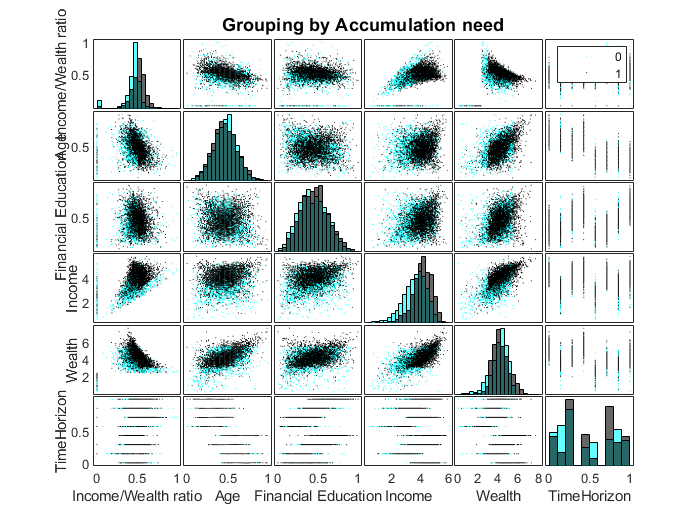

figure
xnames = {'Income/Wealth ratio','Age', 'Financial Education', 'Income', 'Wealth', 'TimeHorizon'};
gplotmatrix(Xsmall,[],Data.AccumulationInvestment, ["c", "k"],[],[],[],'grpbars', xnames)
title('Grouping by Accumulation need')

### **Plotting the variables according Income need**

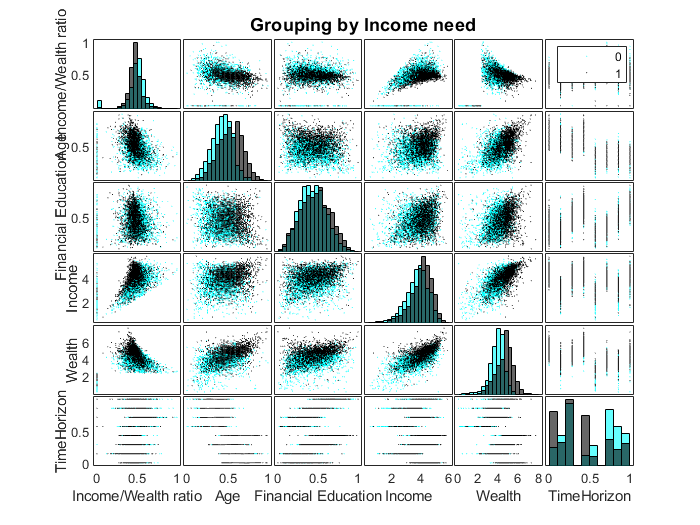

figure
xnames = {'Income/Wealth ratio','Age', 'Financial Education', 'Income', 'Wealth', 'TimeHorizon'};
gplotmatrix(Xsmall,[],Data.IncomeInvestment, ["c", "k"],[],[],[],'grpbars', xnames)
title('Grouping by Income need')

### Preparing the data

XsmallTrain = Xsmall(1:nObsTrain,:);
XsmallTest= Xsmall(nObsTrain+1:end,:);
XsmallTrainTable=table(XsmallTrain(:,1), XsmallTrain(:,2), XsmallTrain(:,3), XsmallTrain(:,4), XsmallTrain(:,5), XsmallTrain(:,6), 'VariableNames',xnames);

### **Running the model which classifies Accumulation need**

NOTE: it will take a while.

|===================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Method | NumLearningC-|    LearnRate |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              | ycles        |              |              |
|===================================================================================================================================|
|    1 | Best   |      0.2504 |      6.1357 |      0.2504 |      0.2504 |   AdaBoostM1 |          123 |    0.0018985 |          455 |
|    2 | Best   |       0.184 |      3.8666 |       0.184 |     0.18779 |   AdaBoostM1 |           96 |      0.19715 |           16 |
|    3 | Best   |      0.1768 |      1.4925 |      0.1768 |     0.17902 |          Bag |           12 |            - |           18 |
|    4 | Accept |      0.2832 |      1.1446 |      0.1768 |   

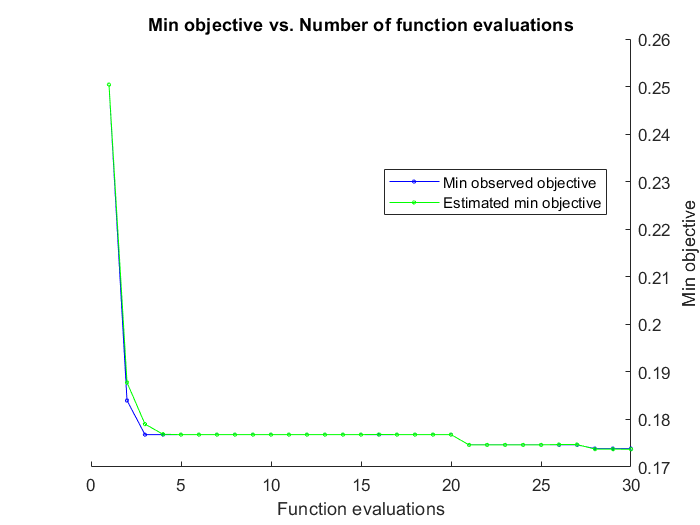


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 251.5035 seconds
Total objective function evaluation time: 220.1617

Best observed feasible point:
    Method    NumLearningCycles    LearnRate    MinLeafSize
    ______    _________________    _________    ___________

     Bag             491              NaN           21     

Observed objective function value = 0.17387
Estimated objective function value = 0.17373
Function evaluation time = 23.1499

Best estimated feasible point (according to models):
    Method    NumLearningCycles    LearnRate    MinLeafSize
    ______    _________________    _________    

MdlOptimum_acc =   ClassificationBaggedEnsemble
                       PredictorNames: {'Income/Wealth ratio'  'Age'  'Financial Education'  'Income'  'Wealth'  'TimeHorizon'}
                         ResponseName: 'Y'
                CategoricalPredictors: []
                           ClassNames: [0    1]
                       ScoreTransform: 'none'
                      NumObservations: 3750
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                           NumTrained: 491
                               Method: 'Bag'
                         LearnerNames: {'Tree'}
                 ReasonForTermination: 'Terminated normally after completing the requested number of training cycles.'
                              FitInfo: []
                   FitInfoDescription: 'None'
                            FResample: 1
                              Replace: 1
                     Us

rng('default')
t = templateTree('Reproducible',true); % in order to get reproducible results
MdlOptimum_acc = fitcensemble(XsmallTrainTable,yInvAccTrain,'OptimizeHyperparameters','auto','Learners',t, ...
    'HyperparameterOptimizationOptions',struct('AcquisitionFunctionName','expected-improvement-plus'))

### Running the model which classifies Income need

|===================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Method | NumLearningC-|    LearnRate |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              | ycles        |              |              |
|===================================================================================================================================|
|    1 | Best   |      0.2424 |      3.1063 |      0.2424 |      0.2424 |   AdaBoostM1 |          123 |    0.0018985 |          455 |
|    2 | Best   |     0.18613 |      3.5699 |     0.18613 |     0.18934 |   AdaBoostM1 |           96 |      0.19715 |           16 |
|    3 | Accept |      0.1904 |     0.83201 |     0.18613 |     0.18779 |          Bag |           12 |            - |           18 |
|    4 | Accept |      0.2424 |     0.68189 |     0.18613 |   

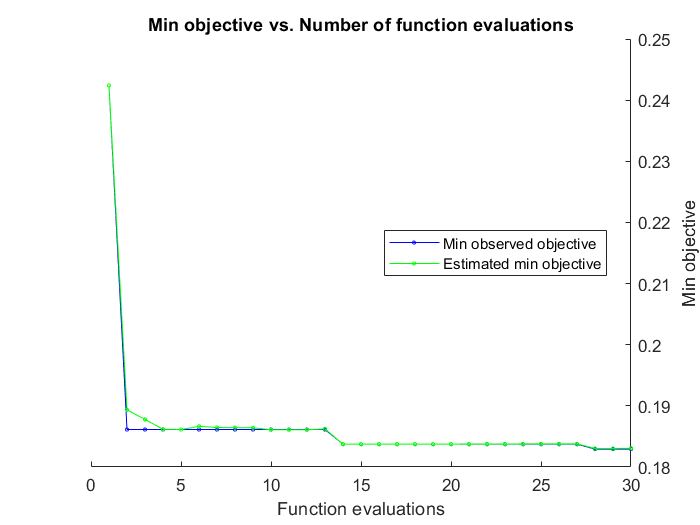


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 316.0335 seconds
Total objective function evaluation time: 291.2481

Best observed feasible point:
    Method    NumLearningCycles    LearnRate    MinLeafSize
    ______    _________________    _________    ___________

     Bag             495              NaN            7     

Observed objective function value = 0.18293
Estimated objective function value = 0.18311
Function evaluation time = 27.5825

Best estimated feasible point (according to models):
    Method    NumLearningCycles    LearnRate    MinLeafSize
    ______    _________________    _________    

MdlOptimum_inc =   ClassificationBaggedEnsemble
                       PredictorNames: {'Income/Wealth ratio'  'Age'  'Financial Education'  'Income'  'Wealth'  'TimeHorizon'}
                         ResponseName: 'Y'
                CategoricalPredictors: []
                           ClassNames: [0    1]
                       ScoreTransform: 'none'
                      NumObservations: 3750
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                           NumTrained: 496
                               Method: 'Bag'
                         LearnerNames: {'Tree'}
                 ReasonForTermination: 'Terminated normally after completing the requested number of training cycles.'
                              FitInfo: []
                   FitInfoDescription: 'None'
                            FResample: 1
                              Replace: 1
                     Us

rng('default')
t = templateTree('Reproducible',true); % in order to get reproducible results
MdlOptimum_inc = fitcensemble(XsmallTrainTable,yInvIncTrain,'OptimizeHyperparameters','auto','Learners',t, ...
    'HyperparameterOptimizationOptions',struct('AcquisitionFunctionName','expected-improvement-plus'))

### Saving the models

save("model_accTIMEclustTOT.mat","MdlOptimum_acc");
save("model_incTIMEclustTOT.mat","MdlOptimum_inc");

### Evaluating predictions for Accumulation and Income need

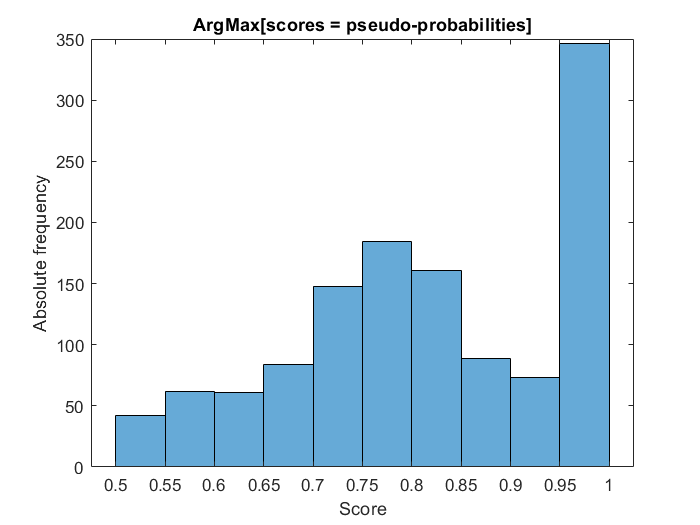

%accumulation need
[labels_acc,scores_acc] = predict(MdlOptimum_acc,XsmallTest);

figure
histogram(max(scores_acc')')
title('ArgMax[scores = pseudo-probabilities]')
xlabel('Score')
ylabel('Absolute frequency')

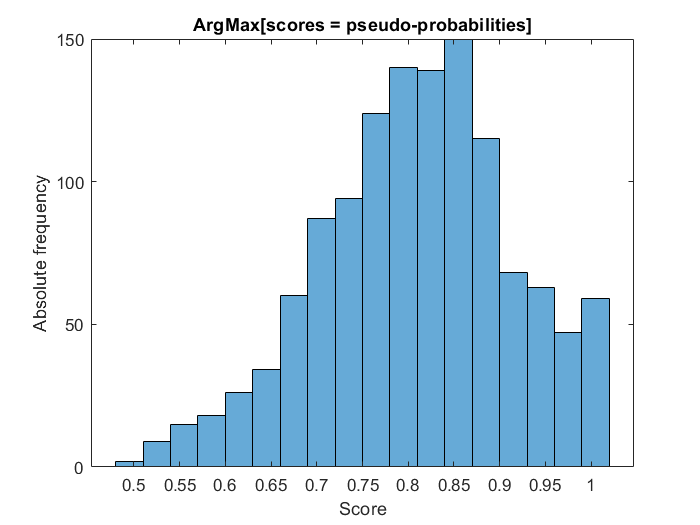

%income need
[labels_inc,scores_inc] = predict(MdlOptimum_inc,XsmallTest);

figure
histogram(max(scores_inc')')
title('ArgMax[scores = pseudo-probabilities]')
xlabel('Score')
ylabel('Absolute frequency')

### Precision, recall and F1 score for Accumulation need

%accumulation products
tp_acc = sum((labels_acc == '1') & (yInvAccTest=='1'));
fp_acc = sum((labels_acc == '1') & (yInvAccTest=='0'));
fn_acc = sum((labels_acc == '0') & (yInvAccTest=='1'));
prec_acc = tp_acc / (tp_acc + fp_acc)

prec_acc = 0.8991

rec_acc = tp_acc / (tp_acc + fn_acc)

rec_acc = 0.7653

F1_acc = 2 * prec_acc * rec_acc / (prec_acc + rec_acc)

F1_acc = 0.8268

The results are similar to the model with the random assignment of Time Horizon and the one obtained through the clustering the categorical features too. Therefore our subdivision has not improved much the quality of the model, that is already pretty good.

### Precision, recall and F1 score for Income need

%income products
tp_inc = sum((labels_inc == '1') & (yInvIncTest=='1'));
fp_inc = sum((labels_inc == '1') & (yInvIncTest=='0'));
fn_inc = sum((labels_inc == '0') & (yInvIncTest=='1'));
prec_inc = tp_inc / (tp_inc + fp_inc)

prec_inc = 0.8935

rec_inc = tp_inc / (tp_inc + fn_inc)

rec_inc = 0.6176

F1_inc = 2 * prec_inc * rec_inc / (prec_inc + rec_inc)

F1_inc = 0.7304

The results are similar to the model with the random assignment of Time Horizon and the one obtained through the clustering the categorical features too. Therefore our subdivision has not improved much the quality of the model, that is already pretty good.

### ROC curve

[X_acc,Y_acc,T_acc,AUC_acc,OPTROCPT_acc] = perfcurve(yInvAccTest,scores_acc(:,2),1);
%area under curve
AUC_acc

AUC_acc = 0.8810

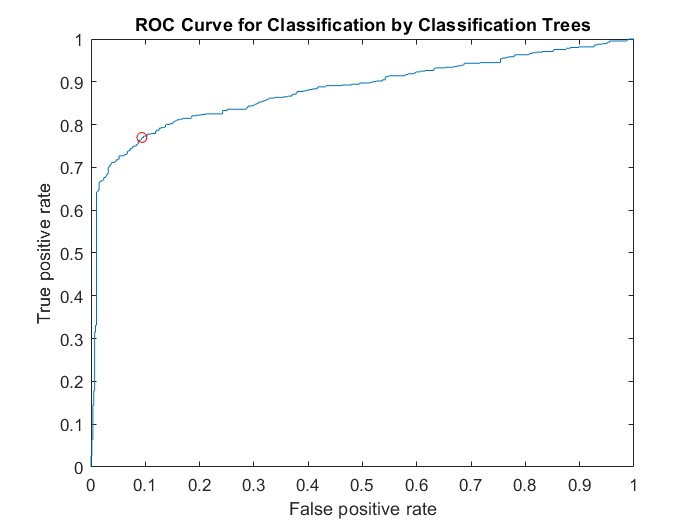

plot(X_acc,Y_acc)
hold on
plot(OPTROCPT_acc(1),OPTROCPT_acc(2),'ro')
xlabel('False positive rate') 
ylabel('True positive rate')
title('ROC Curve for Classification by Classification Trees')
hold off

%optimal operating point accumulation
OPTROCPT_acc

OPTROCPT_acc =     0.0936    0.7699


%threshold of the optimal operating point
T_acc((X_acc==OPTROCPT_acc(1))&(Y_acc==OPTROCPT_acc(2)))

ans = 0.4942

[X_inc,Y_inc,T_inc,AUC_inc,OPTROCPT_inc] = perfcurve(yInvIncTest,scores_inc(:,2),1);
%area under curve
AUC_inc

AUC_inc = 0.8168

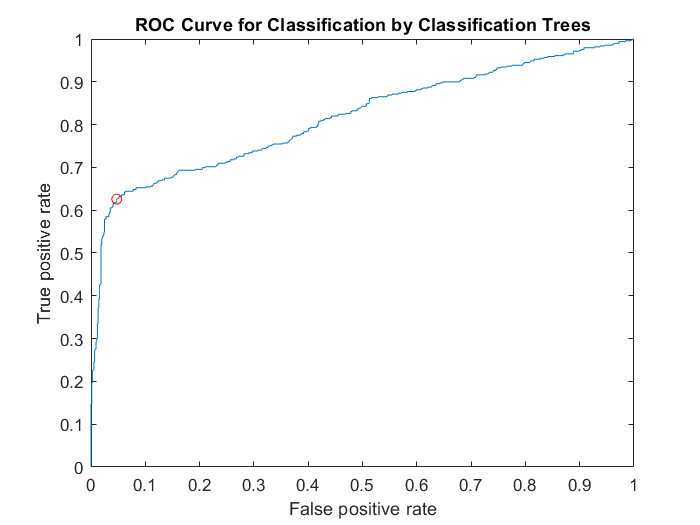

plot(X_inc,Y_inc)
hold on
plot(OPTROCPT_inc(1),OPTROCPT_inc(2),'ro')
xlabel('False positive rate') 
ylabel('True positive rate')
title('ROC Curve for Classification by Classification Trees')
hold off

%optimal operating point accumulation
OPTROCPT_inc

OPTROCPT_inc =     0.0473    0.6258


%threshold of the optimal operating point
T_inc((X_inc==OPTROCPT_inc(1))&(Y_inc==OPTROCPT_inc(2)))

ans = 0.4756

The ROC curves show the goodness-of-fit of the model considered. It plots the trade-off between sensitivity (or TPR) and specificity (1 – FPR). 

This curve confirm that our models provide an accurate classification. Moreover the value of the AUC is very close to 1 in both cases.

We observe that the classification of accumulation needs is a bit more accurate than the income ones.

### **Confusion matrices**

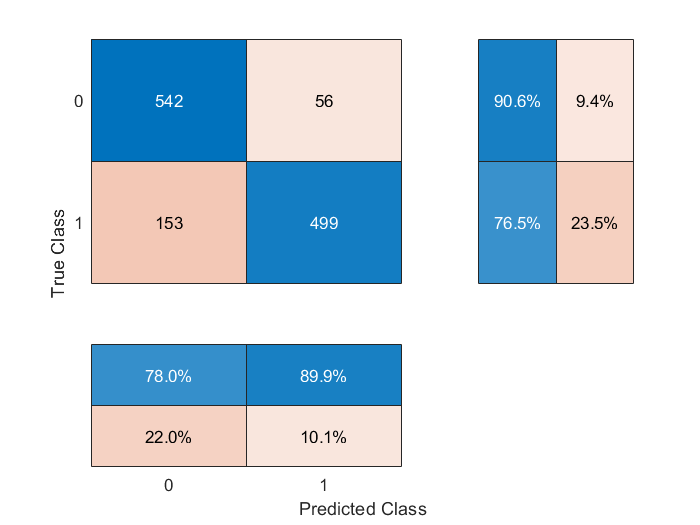

%  Specify 'RowSummary' as 'row-normalized' to display the true positive rates and false positive rates in the row summary. 
%  Also, specify 'ColumnSummary' as 'column-normalized' to display the positive predictive values and false discovery rates in the column summary.
confusionchart(yInvAccTest,labels_acc,'RowSummary','row-normalized','ColumnSummary','column-normalized');

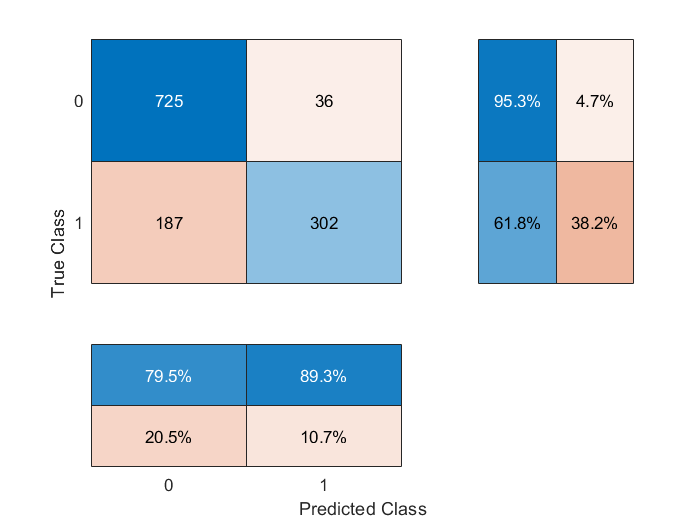

%  Specify 'RowSummary' as 'row-normalized' to display the true positive rates and false positive rates in the row summary. 
%  Also, specify 'ColumnSummary' as 'column-normalized' to display the positive predictive values and false discovery rates in the column summary.
confusionchart(yInvIncTest,labels_inc,'RowSummary','row-normalized','ColumnSummary','column-normalized');

In both cases the model could be improved by reducing the number of false positives: is predicted 0 (no need of accumulation or income product) instead of a true 1 (a need in one of the two).

### Trees

We now show the tree number 20 of our models.

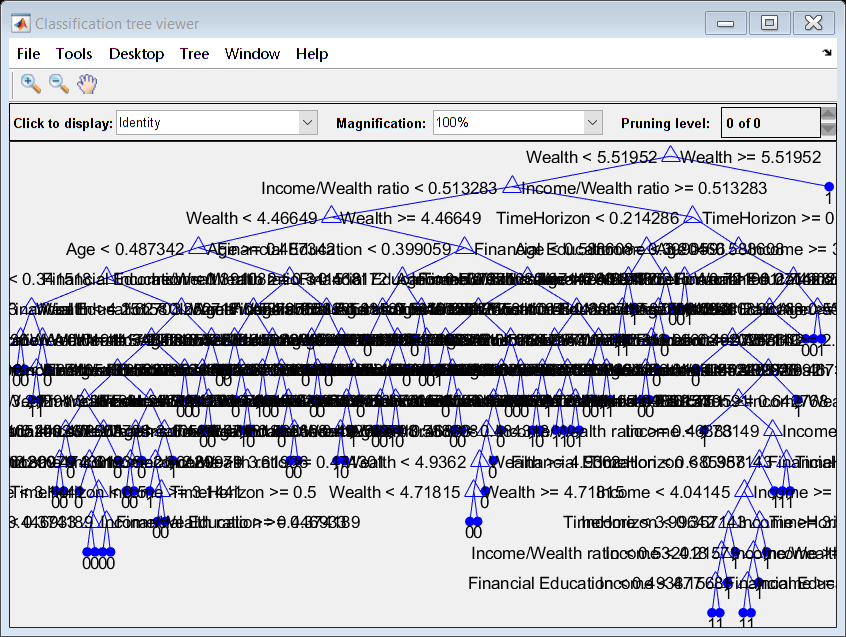

view(MdlOptimum_acc.Trained{20},'Mode','graph')

In this case the tree looks quite complex. It is noticeable that *Income/Wealth ratio, Age and Wealth* are the most important variables, since they are close to the root of the tree. *Time Horizon* is used in the tree and it has a quite relevant position at the top of the tree.

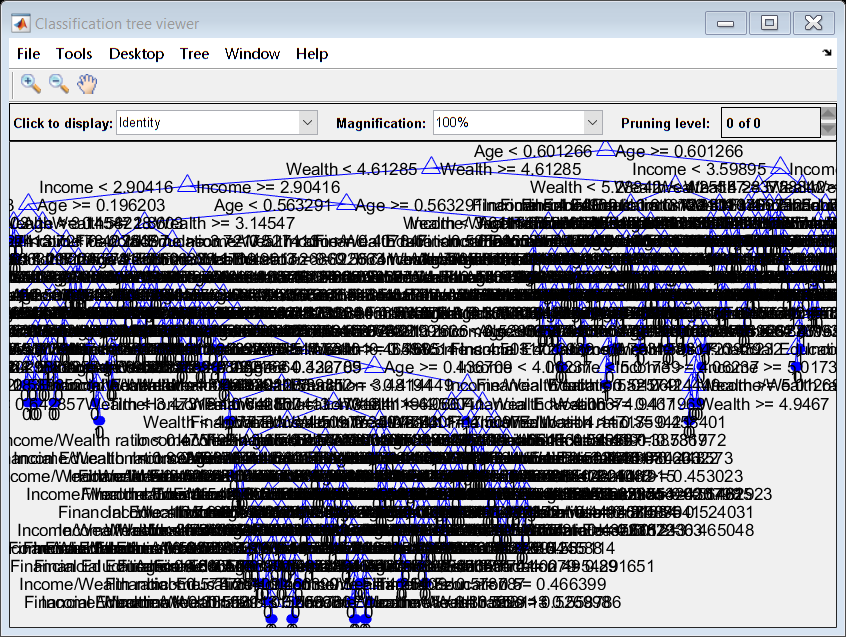

view(MdlOptimum_inc.Trained{20},'Mode','graph')

We notice that in this case the most important variables are *Wealth, Age and Income, *but* Time Horizon* is not as relevant as for the accumulation need.